x=zeros(255,255);
y=zeros(255,255);

    y(127:128,1:255)=1

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

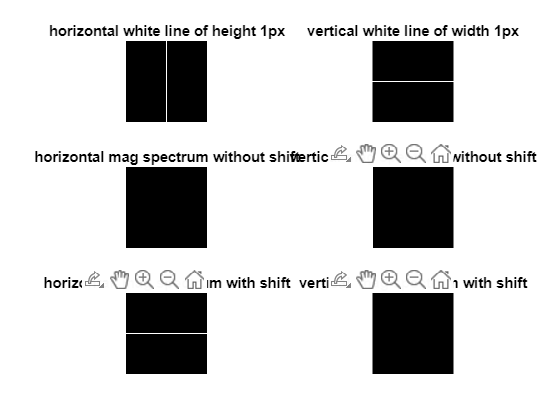

    x(1:255,127:128)=1;


subplot(3,2,1);imshow(x);title('horizontal white line of height 1px');
subplot(3,2,2);imshow(y);title('vertical white line of width 1px');

fft_x=fft2(x);
fft_shift_x=fftshift(fft_x);
abs_fft_shift_x=abs(fft_shift_x);
abs_fft_x=abs(fft_x);
fft_y=fft2(y);
fft_shift_y=fftshift(fft_y);
abs_fft_shift_y=abs(fft_shift_y);
abs_fft_y=abs(fft_y);
subplot(3,2,3);imshow(abs_fft_x);title('horizontal mag spectrum without shift');
subplot(3,2,4);imshow(abs_fft_y);title('vertical mag spectrum without shift');
subplot(3,2,5);imshow(abs_fft_shift_x);title('horizontal  mag spectrum with shift');
subplot(3,2,6);imshow(abs_fft_shift_y);title('vertical  mag spectrum with shift');